# **Training CN-vs-MCIc**

Due to memory (RAM) limits instead of loading the whole Dataset, we are going to process just few images (5, in our case) per time during each fold.

**With the 20-Fold Cross validation we will:**

**    - Find patterns to use for Testing (index==fold) and Training (index!=fold)**

**    - Train AlexNet (until all of the Training images are processed), in particular we will:**

- **Load 5 random RMI training images (single image dimension: 121x145x121)**

- **Transform them into five hundred (5*100) 227x227x3 images (~500MB)**

- **Perform Data Augmentation techniques**

- **Complete the training phase.**

**    - Save the network trained**

**    - Proceed with Validation (until all the Testing images are processed), we will:**

- **Load the 5 RMI Testing images (single image dimension: 121x145x121)**

- **Transform them into five hundred (5*100) 227x227x3 images (~500MB)**

- **Perform Data Augmentation techniques again**

- **Use trained network to perform classification**

- **Add results to a prediction array**

**    - Compute Accurancy**

## **1) Defining the Network**

by modifing the last 3 layers of AlexNet

clear all
warning off

siz=[227 227]; % input size of the CNN (AlexNet)

net = alexnet;
layers=net.Layers; % saving layers
layers(end-2)=fullyConnectedLayer(2,'WeightLearnRateFactor',20,'BiasLearnRateFactor',20);
layers(end-1)=softmaxLayer;
layers(end)=classificationLayer;

## **2) Setting parameters for neural network**

miniBatchSize = 30;
learningRate = 1e-4;
optimizer='sgdm';
options=trainingOptions(optimizer,...
    "MiniBatchSize",miniBatchSize,...
    "InitialLearnRate",learningRate,...
    'MaxEpochs',15,...
    "Verbose",false,...
    "Plots","training-progress");

## **3) Loading the Dataset**

**Loading CN.mat and MCIc.mat**

**Concatenating CN_training, CN_testing, MCIc_training, MCIc_testing in a single cell array**

% Concatenate all dataset files in a single cell array (a cell array is a
% data type with indexed data containers called cells, where each cell can
% contain any type of data)
load CN.mat
load MCIc.mat
dataset=cat(1,CN_training,CN_testing,MCIc_training,MCIc_testing);

% Create label array
lengthClass1=(length(CN_training)+length(CN_testing));
lengthClass2=(length(MCIc_training)+length(MCIc_testing));
label(1:lengthClass1)=1; %Cognitive Normal = 1
label(lengthClass1:lengthClass1+lengthClass2)=2;

clear CN_training CN_testing MCIc_training MCIc_testing lengthClass1 lengthClass2

**In this section we find patterns we will use for Testing (Indices==fold) and Training (Indices!=fold)**

% Splitting the dataset in Training and Testing for this fold
fold=3;

load indices_CN-vs-MCIc.mat

trainingData=dataset(Indices~=fold);
trainingLabel=label(Indices~=fold);

testData=dataset(Indices==fold);
testLabel=label(Indices==fold);

clear dataset label

**Shuffling the dataset**

Instead of directly shuffling trainingData, to save computation we create and shuffle a indicesVector

indicesVector=[1:length(trainingData)]; % Containg indices from 1 to trainingData length (~228)
indicesVector=indicesVector(randperm(length(indicesVector))); % Shuffle vector of indices


## **4) Training**

**This section of code will be repeatedly executed until all the Training images are processed.**

count=1 % image to test

count = 1

for i=1:length(indicesVector)

count = 2

count = 3

count = 4

count = 5

count = 6

ans =    227   227     3   500


count = 7

count = 8

count = 9

count = 10

count = 11

ans =    227   227     3   500


count = 12

count = 13

count = 14

count = 15

count = 16

ans =    227   227     3   500


count = 17

count = 18

count = 19

count = 20

count = 21

ans =    227   227     3   500


count = 22

count = 23

count = 24

count = 25

count = 26

ans =    227   227     3   500


count = 27

count = 28

count = 29

count = 30

count = 31

ans =    227   227     3   500


count = 32

count = 33

count = 34

count = 35

count = 36

ans =    227   227     3   500


count = 37

count = 38

count = 39

count = 40

count = 41

ans =    227   227     3   500


count = 42

count = 43

count = 44

count = 45

count = 46

ans =    227   227     3   500


count = 47

count = 48

count = 49

count = 50

count = 51

ans =    227   227     3   500


### **        4.1) Loading 5 RMI training images**

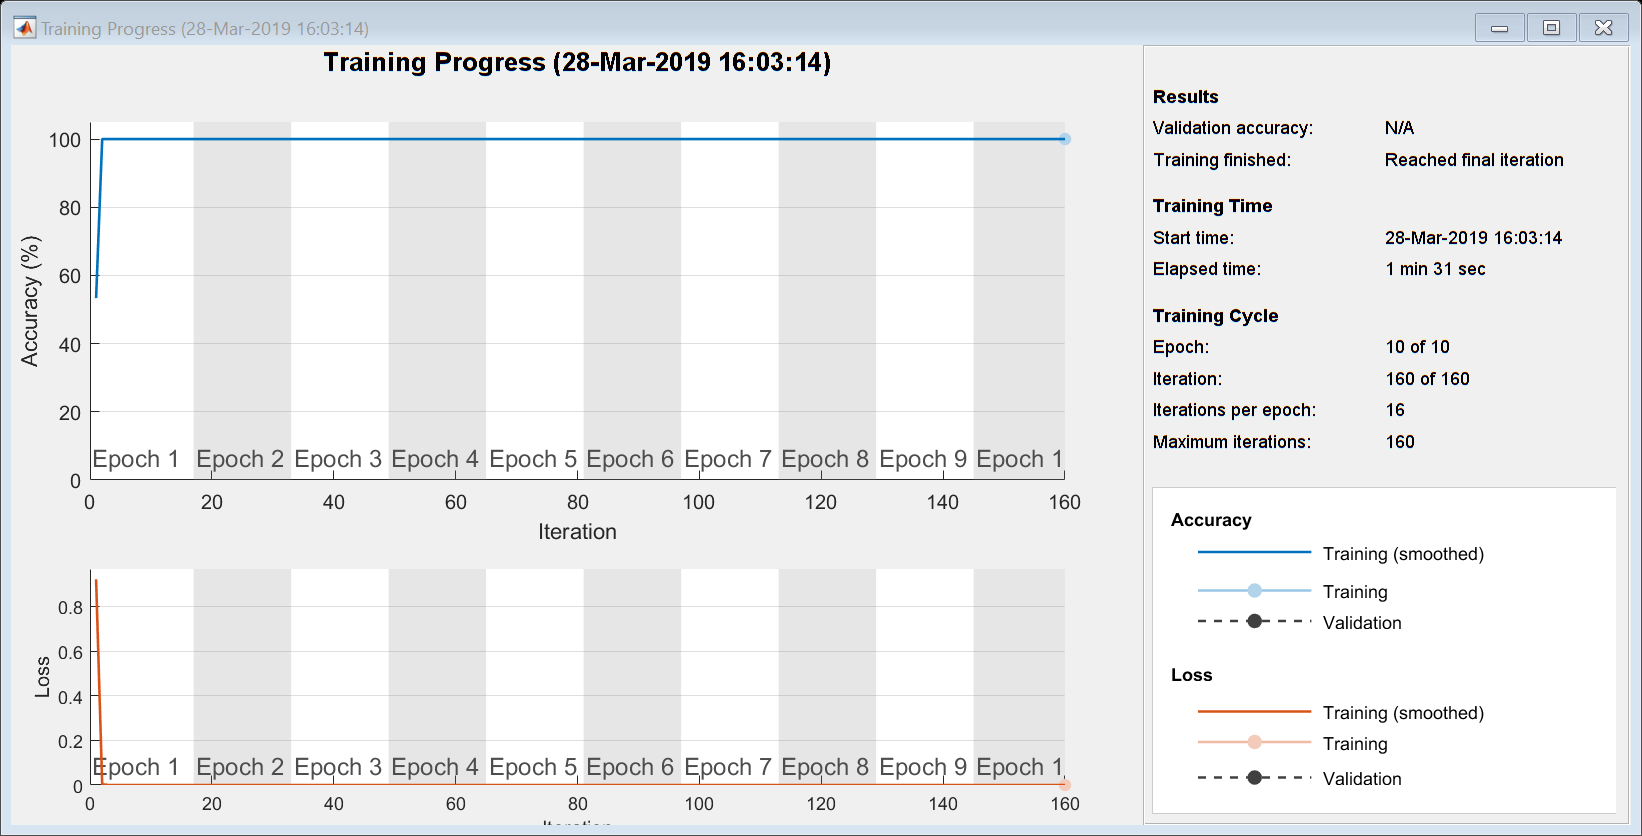

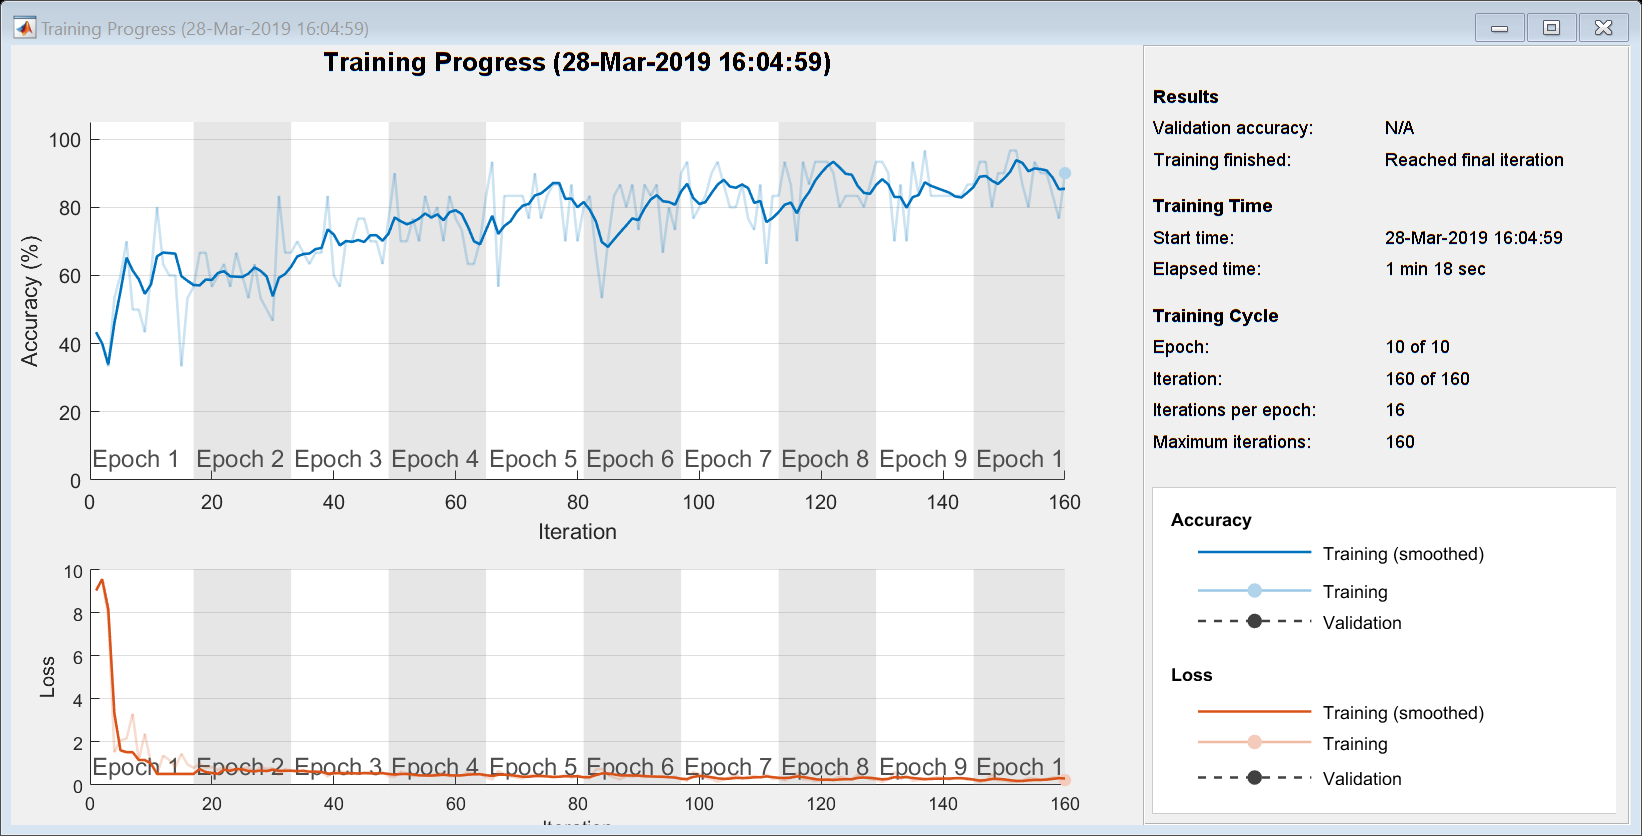

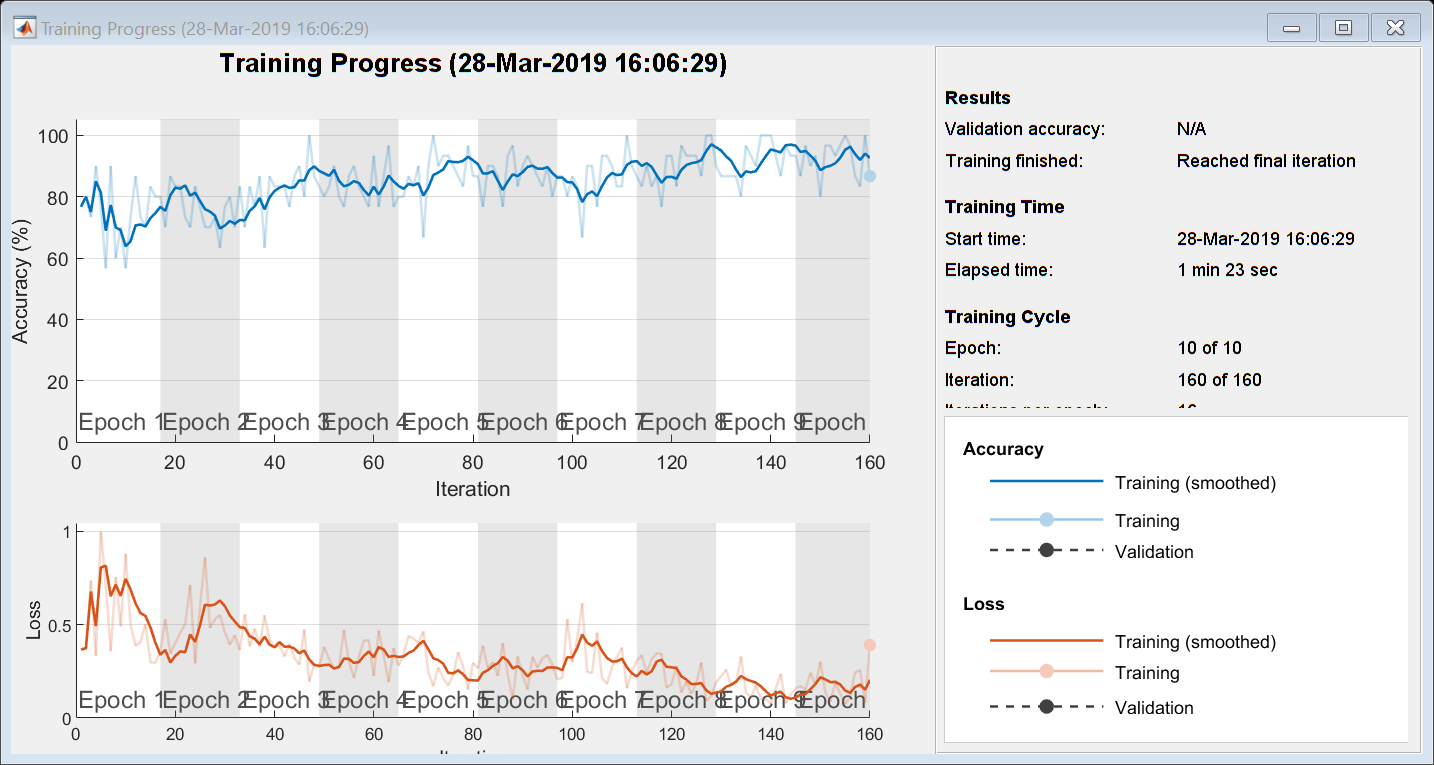

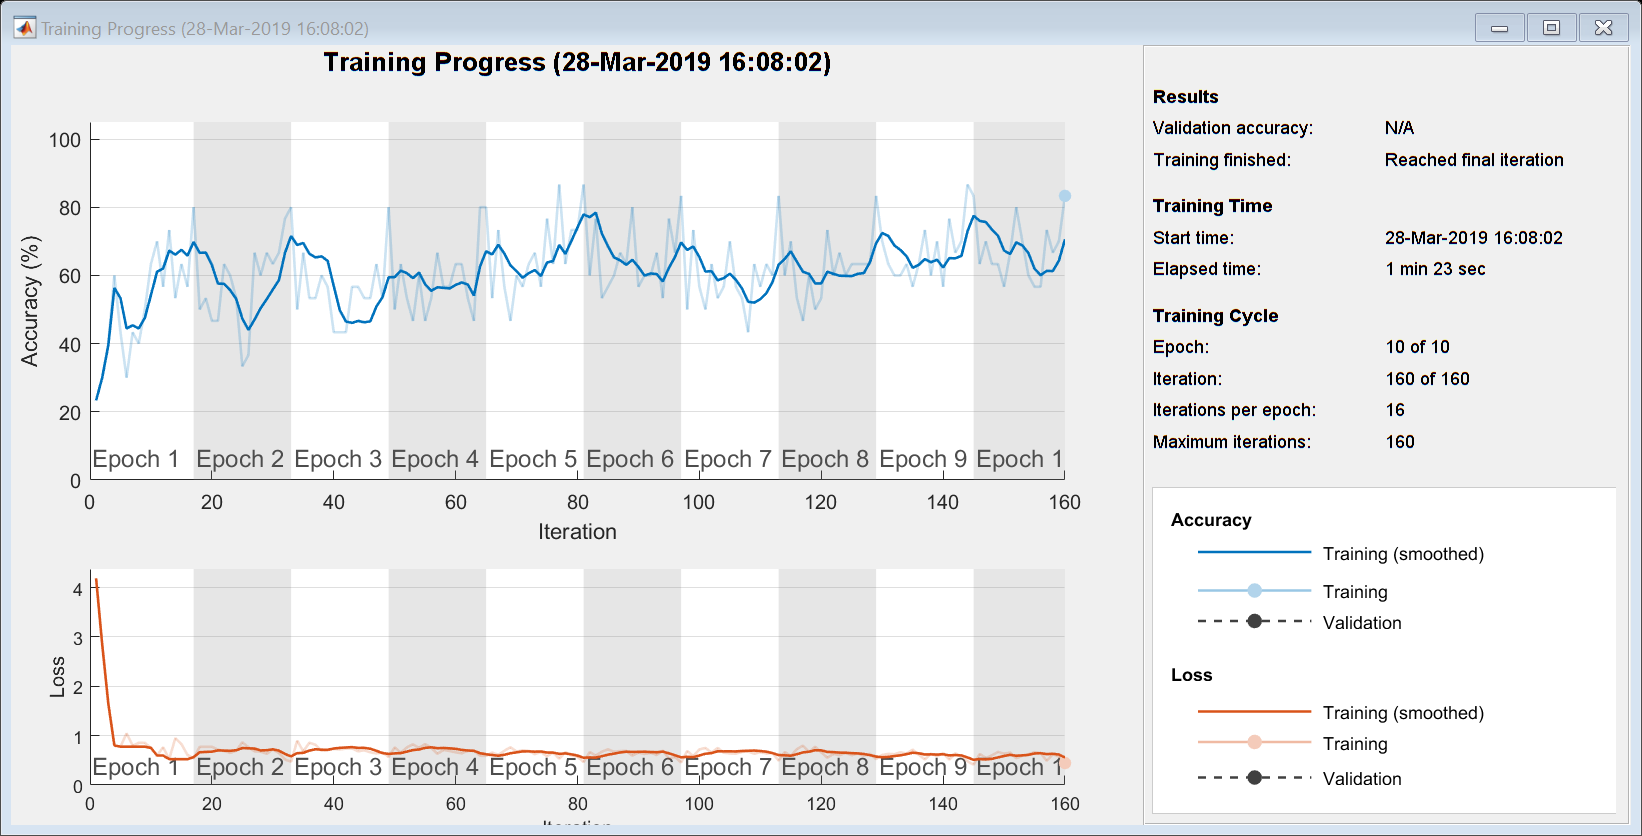

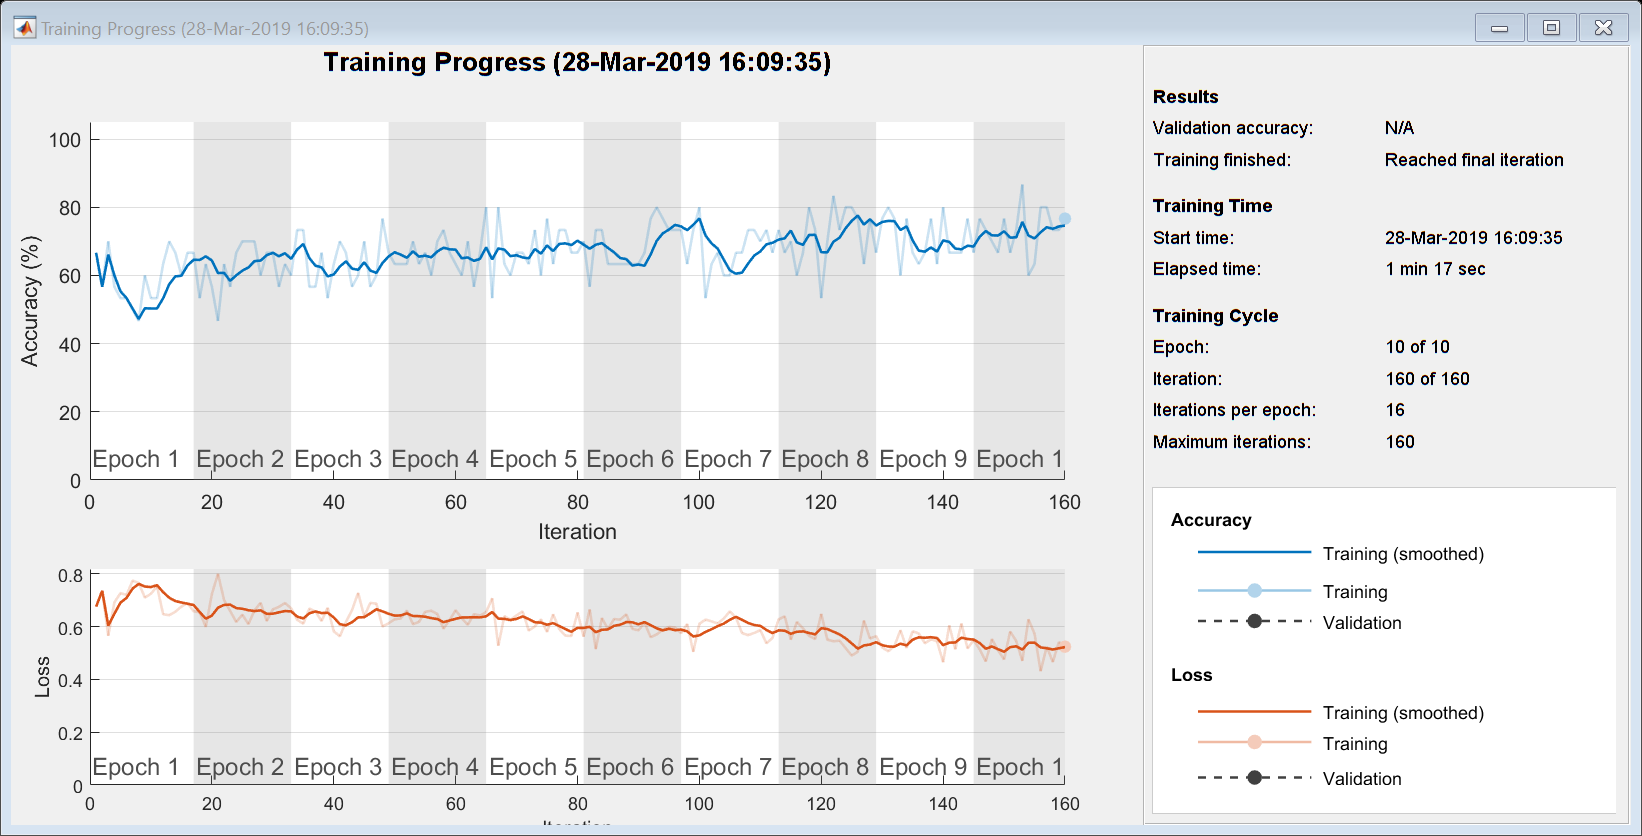

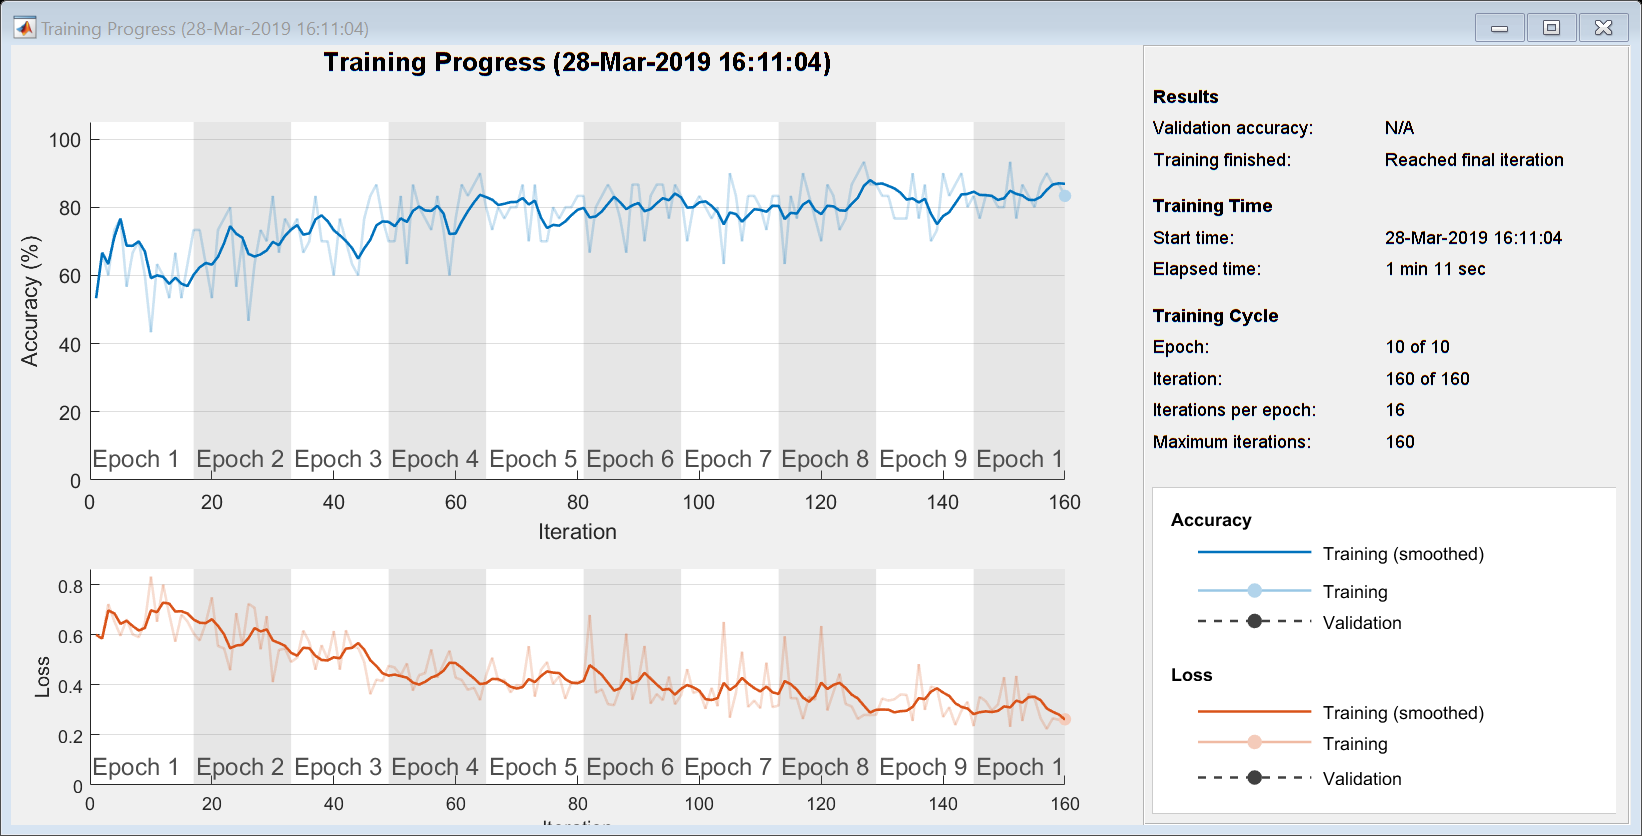

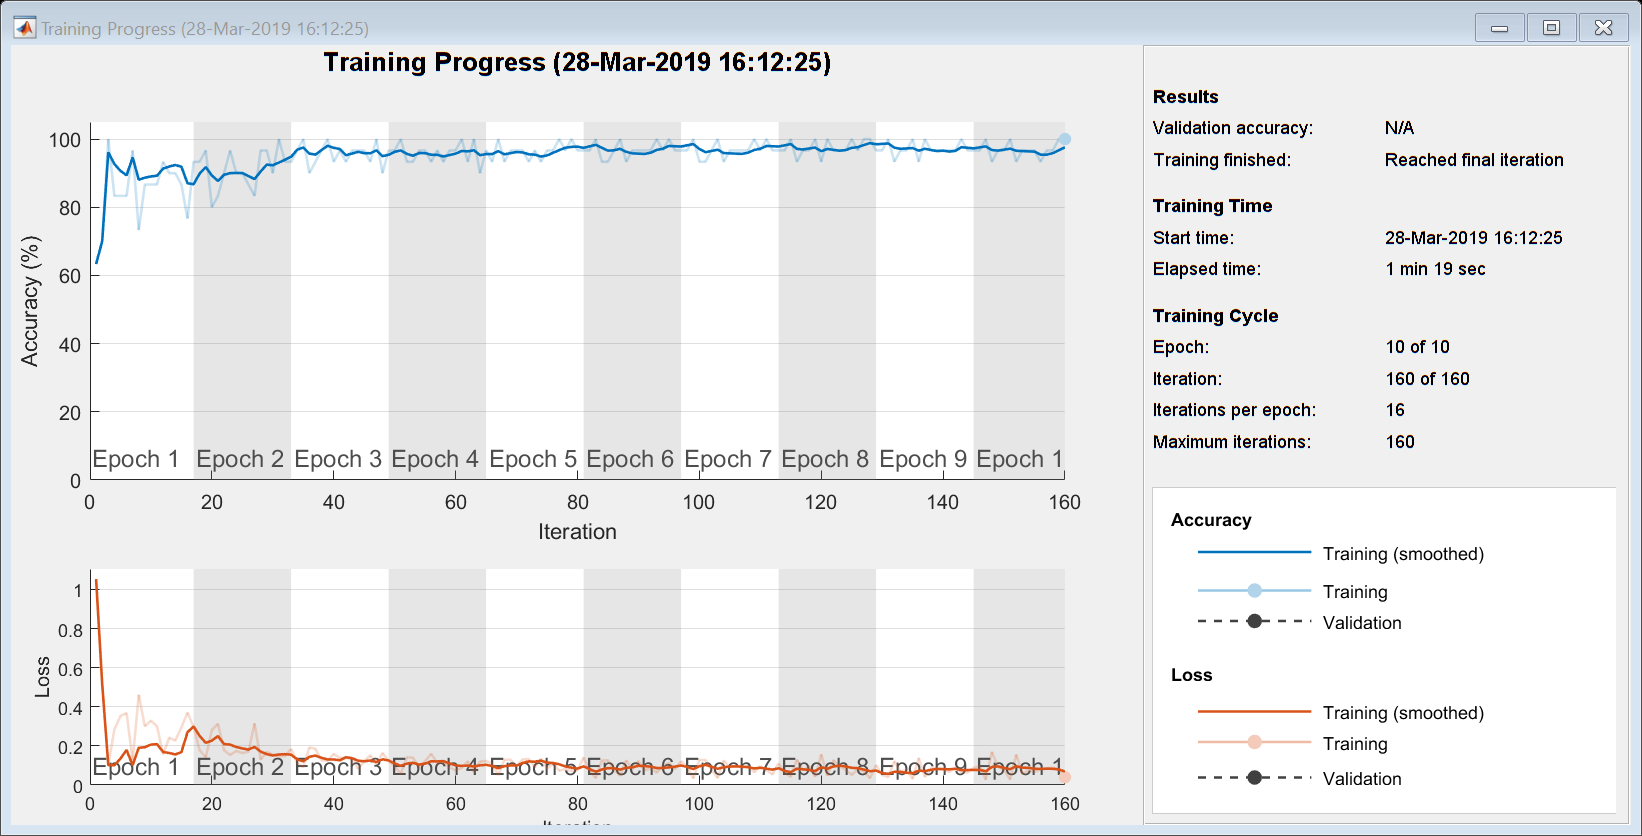

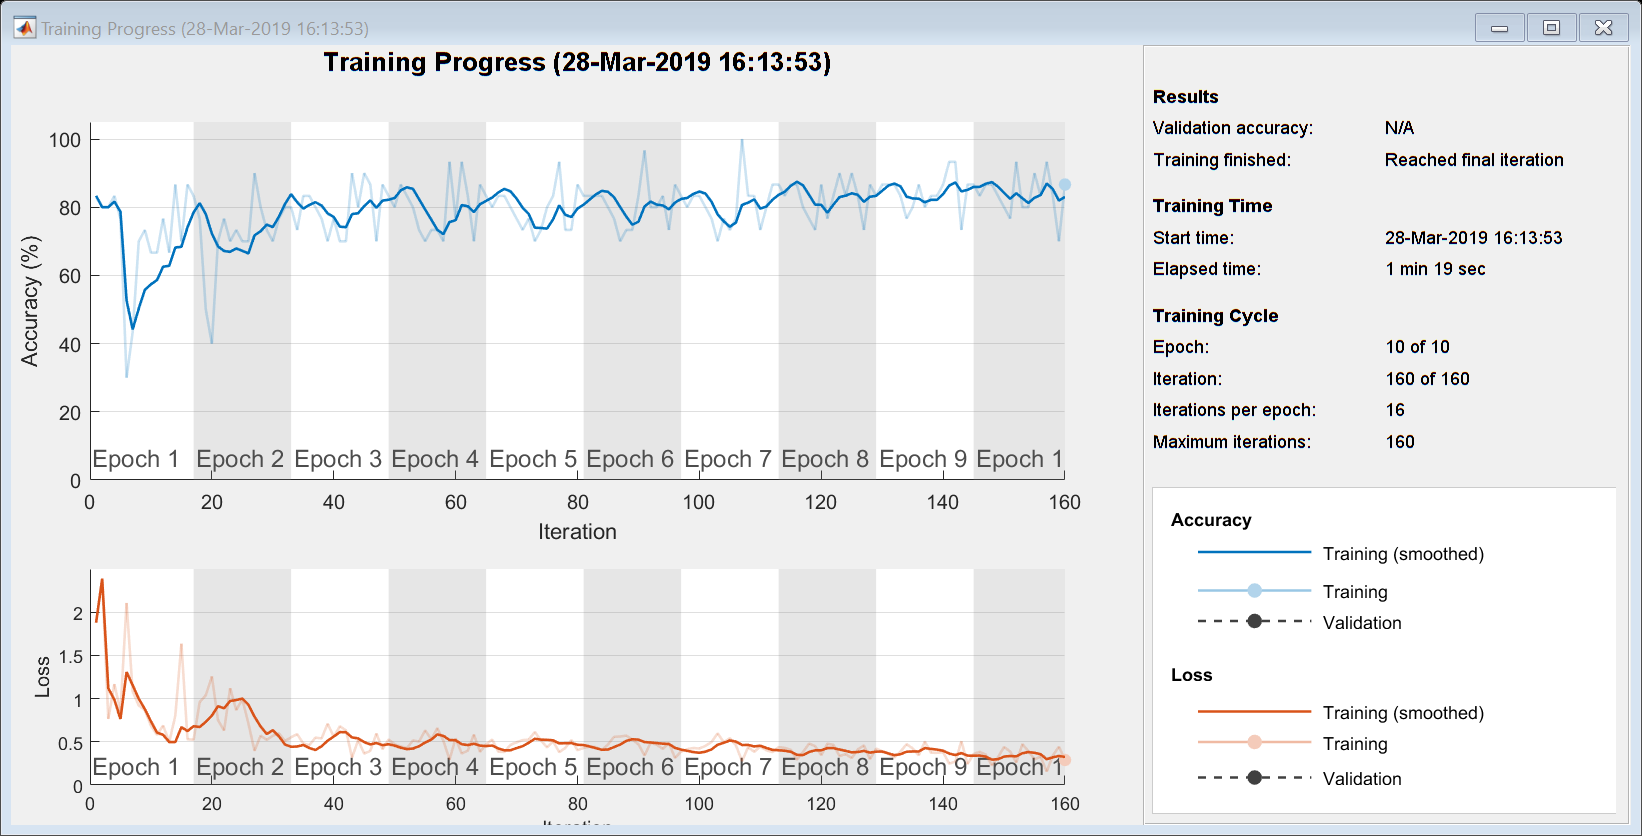

    setSize=5;
    trainingImages=[];
    label=[]; % labels of classes 
    labelID=[]; % labels of ID

    tmpTR=1;
    for mri=1:setSize
        
        % Extract single MRI
        IMG=trainingData{indicesVector(count)};
        
        % Transform MRI picture into 100 images 227x227x3
        IMG=mriToCNN(IMG,siz);
        trainingImages(:,:,:,tmpTR:tmpTR+size(IMG,4)-1)=IMG;
        
        % Return label vector the labels of the new 100 pictures
        class=trainingLabel(indicesVector(count));
        label(tmpTR:tmpTR+size(IMG,4)-1)=class;
        


totLabelsID =

     []



        % Saving single person's ID
        labelID(tmpTR:tmpTR+size(IMG,4)-1)=indicesVector(count);
        
        tmpTR=tmpTR+size(IMG,4); %Increasing counter by 100
        
        clear IMG;
        
        count=count+1
        if count>length(indicesVector)
            break;
        end 
        
    end
    
    % The label is a series of one hundred "1" and one hundred "2", so we
    % decided to shuffle again to obtain:
    indicesVector2=[1:length(label)];
    indicesVector2=indicesVector2(randperm(length(indicesVector2))); % Shuffling vector of indices
    label=label(indicesVector2);
    labelID=labelID(indicesVector2);
    trainingImages=trainingImages(:,:,:,indicesVector2);
    size(trainingImages)

### **        4.2) Performing Data augmentation techniques on the TrainSet**

%imageAugmenter = imageDataAugmenter( ...
        %'RandXReflection',true, ...
        %'RandXScale',[1 2], ...
        %'RandYReflection',true, ...
        %'RandYScale',[1 2],...
        %'RandRotation',[-10 10],...
        %'RandXTranslation',[0 5],...
        %'RandYTranslation', [0 5]);
    %trainingImages = augmentedImageSource(imageSize,trainingImages,categorical(y'),'DataAugmentation',imageAugmenter);

### **        4.3) Training**

    valueset = [1:2];
    Y=categorical(label',valueset);
    
    [trainedNet,info]=trainNetwork(trainingImages,Y,layers,options);
    

### **        4.4) Re-use the layers of the trained network**

    layers=trainedNet.Layers;
    
    if count>length(indicesVector)

TP = 99

        break;

TN = 558

    end

FP = 242

end

FN = 201

## **5) Validation**

### **5.1) Loading TestSet**

totPredictions=[];

precision = 0.2903

totLabels=[];

recall = 0.3300

totLabelsID=[]

f1 = 0.3089

specificity = 0.3025

count=1; % image to test

accuracy = 0.5973

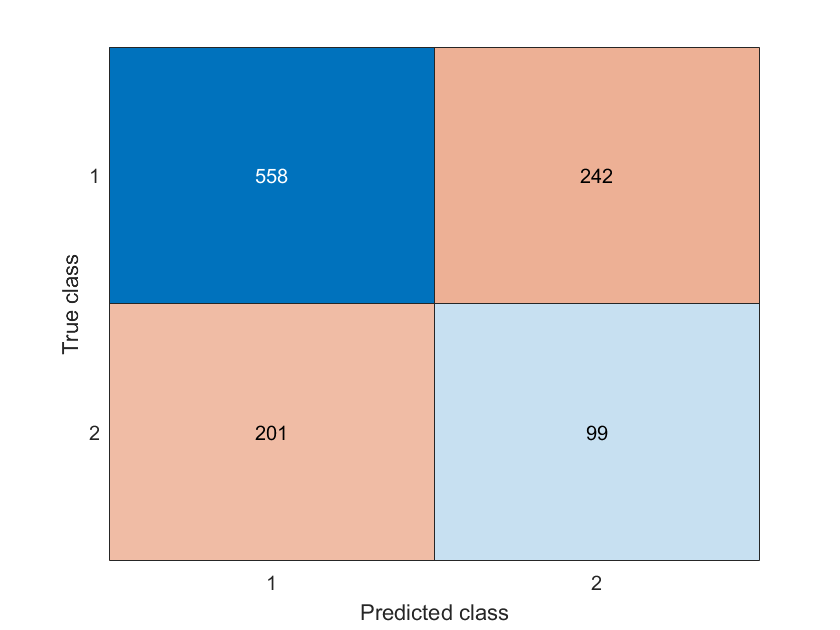

ans =   ConfusionMatrixChart with properties:

    NormalizedValues: [2×2 double]
         ClassLabels: [2×1 double]

  Show all properties


for i=1:length(testData)
    label=[];   % labels of classes 
    labelID=[]; % labels of ID
    validationImages=[];

    tmpTR=1;
    for mri=1:setSize
        
        % Extract single MRI
        IMG=testData{count};
        
        % Transform MRI picture into one hundred 227x227x3 images
        IMG=mriToCNN(IMG,siz);
        validationImages(:,:,:,tmpTR:tmpTR+size(IMG,4)-1)=IMG;
        
        % Return label vector the labels of the new 100 pictures
        class=testLabel(count);
        label(tmpTR:tmpTR+size(IMG,4)-1)=class;
        
        % Saving single person's ID
        labelID(tmpTR:tmpTR+size(IMG,4)-1)=count;
        
        tmpTR=tmpTR+size(IMG,4); %Increasing counter by 100
        
        clear IMG;
        
        count=count+1;
        if count>length(testData)
            break;
        end   
    end

### **        5.2) Data Augmentation on TestSet**

%imageAugmenter = imageDataAugmenter( esempio: 'RandRotation', [-180 180])
%esempio, inserire prima di validationImages la dimensione: imageSize = [28 28 1];
%validationImages = augmentedImageSource((imageSize,XTrain,YTrain,'DataAugmentation',imageAugmenter)

### **        5.3) Validatation on 500 images**

    predictions = classify(trainedNet,validationImages);

    totPredictions=cat(1,totPredictions,predictions);
    totLabels=cat(2,totLabels,label);
    totLabelsID=cat(2,totLabelsID,labelID);
    
    clear validationImages predictions label
    
    if count>length(testData)
        break;
    end
end
predictions=totPredictions;
label=totLabels;
labelID=totLabelsID;


## **6) Metrics**

predictions=double(predictions);

TP= sum(and((predictions==2)',label==2))
TN= sum(and((predictions==1)',label==1))
FP= sum(and((predictions==2)',label==1))
FN= sum(and((predictions==1)',label==2))

precision= TP/(TP+FP)
recall=TP/(TP+FN)
f1=2*(precision*recall)/(precision+recall)
specificity=FP/(FP+TN)
accuracy=(TP+TN)/(TP+TN+FP+FN)

%accuracy = sum(predictions' == label)/numel(label)

confusionchart(label,predictions)

## **7) Save the trained model**

save("trainedModel"+fold+".mat", "trainedNet");

**Function that transforms a MRI picture into 100 227x227x3 images (~100MB)**

function [IMG]=mriToCNN(IMG,siz) 
    % Removing NaN values
    IMG(find(isnan(IMG)))=0;
    
    % Creating one hundred 227x227x3 pictures
    % Resizing each 121x145 slice to 227x227
    % Excluding the first and the last 10 layers because are almost completely made up fo zeroes
    clear RID
    for livello=11:110
        RID(:,:,1,livello-10)=imresize(IMG(:,:,livello),[siz(1) siz(2)]);
        RID(:,:,2,livello-10)=imresize(IMG(:,:,livello),[siz(1) siz(2)]);
        RID(:,:,3,livello-10)=imresize(IMG(:,:,livello),[siz(1) siz(2)]);
    end
    
    clear IMG
    
    % Normalizing values <--------------------------------- TODO: find a better normalization
    M=max(RID(:));
    IMG=floor(RID.*(255/M));
end